### Bridge of Doom Project

clc, clear all

% define variables
syms u

% beta * t = u
% lower beta = lower speed
beta = 0.3;

% Define equations
ri=4*0.3960*cos(2.65*(beta*u + 1.4));
rj=-4*0.99*sin(beta*u+1.4);
rk=0*u;
r=[ri,rj,rk];

% Assume u is positive
assume(u,{'real','positive'})

% ---- FIND UNIT TANGENT VECTOR ----
dr=diff(r,u);
T_hat=simplify(dr./norm(dr))

$$T\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{53\,\sin\left(\frac{159\,u}{200}+\frac{371}{100}\right)}{\sigma_{1}} & -\frac{50\,\cos\left(\frac{3\,u}{10}+\frac{7}{5}\right)}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2500\,{\cos\left(\frac{3\,u}{10}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{159\,u}{200}+\frac{371}{100}\right)}^{2}} \end{array}$$


% ---- FIND UNIT NORMAL VECTOR----
dT_hat=diff(T_hat,u);
N_hat=dT_hat/norm(dT_hat);
N_hat=simplify(N_hat)

$$N\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{2\,\left(290175\,\sigma_{7}+421350\,\sigma_{6}+131175\,\sigma_{5}\right)}{\sigma_{1}} & \frac{337080\,\sigma_{4}+615171\,\sigma_{3}+278091\,\sigma_{2}}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=159\,\sqrt{2500\,{\left(73\,\sigma_{7}+106\,\sigma_{6}+33\,\sigma_{5}\right)}^{2}+2809\,{\left(40\,\sigma_{4}+73\,\sigma_{3}+33\,\sigma_{2}\right)}^{2}}\\ \sigma_{2}=\sin\left(\frac{189\,u}{100}+\frac{441}{50}\right)\\ \sigma_{3}=\sin\left(\frac{129\,u}{100}+\frac{301}{50}\right)\\ \sigma_{4}=\sin\left(\frac{3\,u}{10}+\frac{7}{5}\right)\\ \sigma_{5}=\cos\left(\frac{279\,u}{200}+\frac{651}{100}\right)\\ \sigma_{6}=\cos\left(\frac{159\,u}{200}+\frac{371}{100}\right)\\ \sigma_{7}=\cos\left(\frac{39\,u}{200}+\frac{91}{100}\right) \end{array}$$


% ---- FIND VELOCITY ----
v = simplify(dr)

$$v = \left(\begin{array}{ccc} -\frac{15741\,\sin\left(\frac{159\,u}{200}+\frac{371}{100}\right)}{12500} & -\frac{297\,\cos\left(\frac{3\,u}{10}+\frac{7}{5}\right)}{250} & 0 \end{array}\right)$$

speed = simplify(norm(v))

$$speed = \frac{297\,\sqrt{2500\,{\cos\left(\frac{3\,u}{10}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{159\,u}{200}+\frac{371}{100}\right)}^{2}}}{12500}$$


% ---- FIND ANGULAR VELOCITY ----
angular_velocity = simplify(cross(T_hat,diff(T_hat,u)))

$$angular\_velocity = \left(\begin{array}{ccc} 0 & 0 & -\frac{11607\,\cos\left(\frac{99\,u}{200}+\frac{231}{100}\right)+5247\,\cos\left(\frac{219\,u}{200}+\frac{511}{100}\right)}{10000\,\cos\left(\frac{3\,u}{5}+\frac{14}{5}\right)-11236\,\cos\left(\frac{159\,u}{100}+\frac{371}{50}\right)+21236} \end{array}\right)$$

### Left and Right Wheel Velocities

% ---- FIND WHEELs ----
% since angular velocity is always in k hat directly only,
% multiplying norm(angular_velocity) with sign(angular_velocity)
% is the same as the dot product of angular velocity with k hat

d = 0.235;
v_left_wheel = simplify(speed - (norm(angular_velocity) * sign(angular_velocity) * d)/2)

$$v\_left\_wheel = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{1} & \sigma_{1} & \sigma_{1}+\frac{47\,\left|11607\,\sigma_{4}+5247\,\sigma_{2}\right|\,\mathrm{sign}\left(\frac{73\,\sigma_{4}+33\,\sigma_{2}}{2500\,\sigma_{5}-2809\,\sigma_{3}+5309}\right)}{400\,\left(10000\,\sigma_{5}-11236\,\sigma_{3}+21236\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{297\,\sqrt{2500\,{\cos\left(\frac{3\,u}{10}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{159\,u}{200}+\frac{371}{100}\right)}^{2}}}{12500}\\ \sigma_{2}=\cos\left(\frac{219\,u}{200}+\frac{511}{100}\right)\\ \sigma_{3}=\cos\left(\frac{159\,u}{100}+\frac{371}{50}\right)\\ \sigma_{4}=\cos\left(\frac{99\,u}{200}+\frac{231}{100}\right)\\ \sigma_{5}=\cos\left(\frac{3\,u}{5}+\frac{14}{5}\right) \end{array}$$

v_right_wheel = simplify(speed + (norm(angular_velocity) * sign(angular_velocity) * d)/2)

$$v\_right\_wheel = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{1} & \sigma_{1} & \sigma_{1}-\frac{47\,\left|11607\,\sigma_{4}+5247\,\sigma_{2}\right|\,\mathrm{sign}\left(\frac{73\,\sigma_{4}+33\,\sigma_{2}}{2500\,\sigma_{5}-2809\,\sigma_{3}+5309}\right)}{400\,\left(10000\,\sigma_{5}-11236\,\sigma_{3}+21236\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{297\,\sqrt{2500\,{\cos\left(\frac{3\,u}{10}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{159\,u}{200}+\frac{371}{100}\right)}^{2}}}{12500}\\ \sigma_{2}=\cos\left(\frac{219\,u}{200}+\frac{511}{100}\right)\\ \sigma_{3}=\cos\left(\frac{159\,u}{100}+\frac{371}{50}\right)\\ \sigma_{4}=\cos\left(\frac{99\,u}{200}+\frac{231}{100}\right)\\ \sigma_{5}=\cos\left(\frac{3\,u}{5}+\frac{14}{5}\right) \end{array}$$

### Define linspace for u for plotting

% define 100evenly spaced points between 0 and 3.2
u_num = linspace(0,3.2/beta,100); 

### Plot Bridge Centerline and Vectors

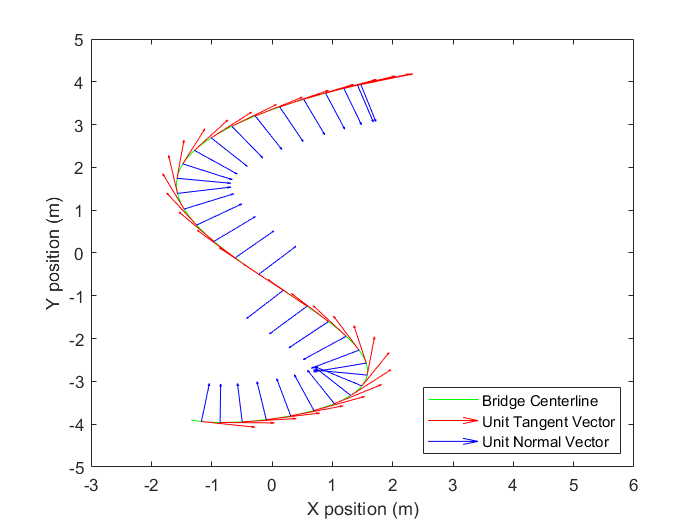

clf;
% plot the centerline
r_num(1,:)=double(subs(r,[u],[u_num(1)]));
plot(r_num(:,1),r_num(:,2),'g'),axis([-3 6 -5 5]),hold on % plot the entire curve

%we will also convert to a number of type double
for n=1:length(u_num)
    T_hat_num(n,:)=double(subs(T_hat,[u],[u_num(n)]));
    N_hat_num(n,:)=double(subs(N_hat,[u],[u_num(n)]));

    % plot the vectors less frequently
     if mod(n, 3) == 0 || n == length(u_num)
         quiver(r_num(n,1),r_num(n,2),T_hat_num(n,1),T_hat_num(n,2),'r') % plot the unit tangent
         quiver(r_num(n,1),r_num(n,2),N_hat_num(n,1),N_hat_num(n,2),'b') % plot the unit normal
     end
end
drawnow
xlabel('X position (m)')
ylabel('Y position (m)')
legend('Bridge Centerline', 'Unit Tangent Vector', 'Unit Normal Vector','Location','southeast')

### Plot Speed

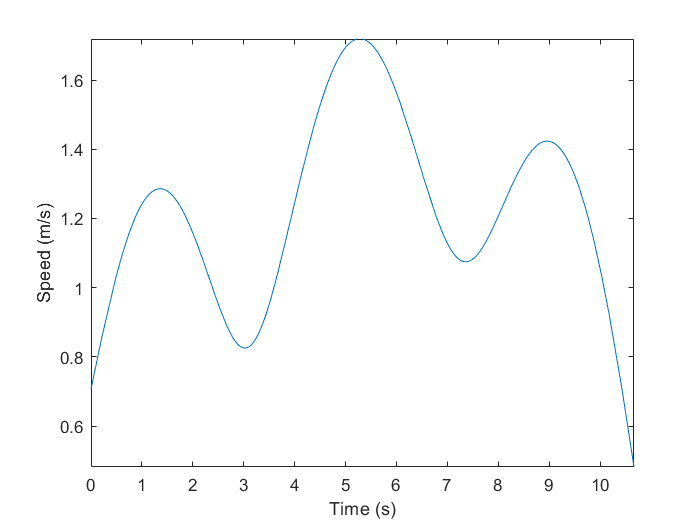

clf;
fplot(speed,[0 3.2/beta])
xlabel('Time (s)')
ylabel('Speed (m/s)')

### Plot Angular Velocity

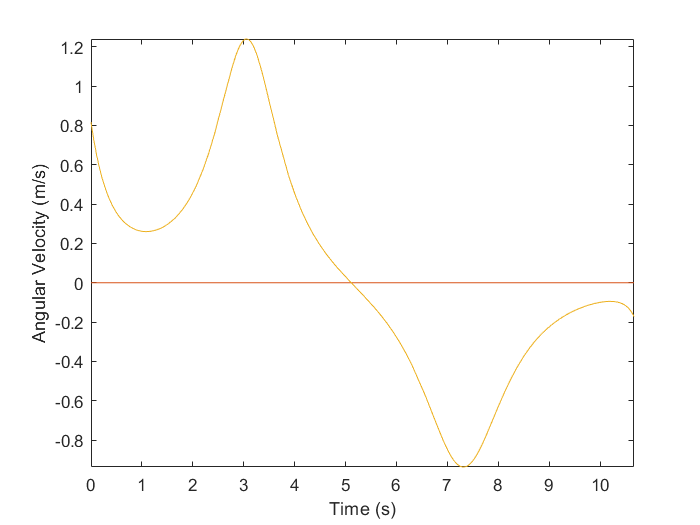

clf;
fplot(angular_velocity,[0 3.2/beta])
xlabel('Time (s)')
ylabel('Angular Velocity (m/s)')

### Plot Left and Right Wheel Velocities

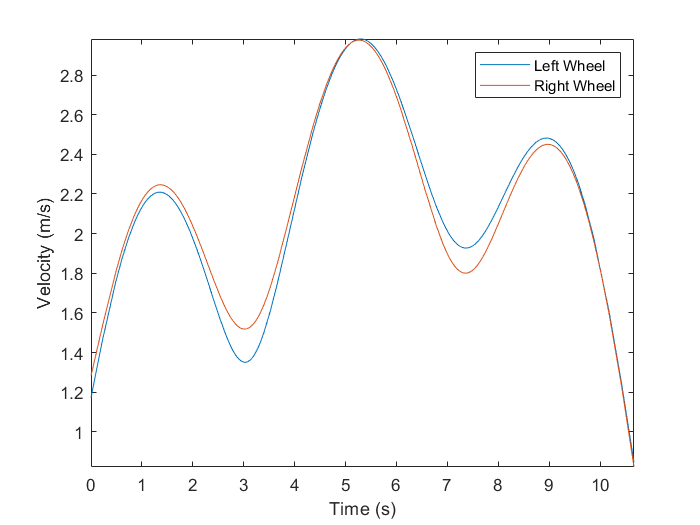

clf; 
fplot(norm(v_left_wheel),[0 3.2/beta]); hold on;
fplot(norm(v_right_wheel),[0 3.2/beta]); hold off;

xlabel('Time (s)')
ylabel('Velocity (m/s)')
legend('Left Wheel', 'Right Wheel')

Unusued Calculations

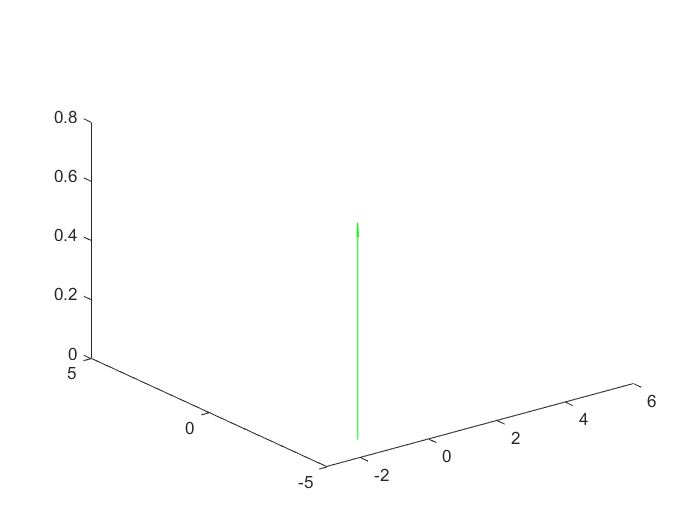

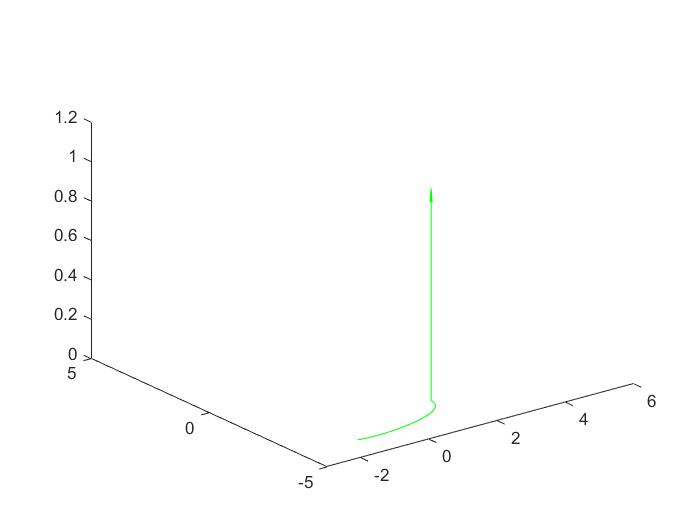

% ==== UNUSED ==== %

% ---- FIND UNIT BINORMAL VECTOR----
B_hat=cross(T_hat,N_hat);
B_hat=simplify(B_hat)

% ---- FIND CURVATURE ----
kappa=norm(dT_hat)/norm(dr);
kappa=simplify(kappa)

% ---- FIND TORSION ----
tau=-dot(N_hat,(diff(B_hat,u)/norm(dr)))

% ---- FIND ACCELERATION ----
accel = simplify(diff(v, u))
% decompose accel in terms of % tangent
aT = simplify(dot(accel, T_hat))
aN = simplify(dot(accel, N_hat))